# RunsTestStudy

Tests if computer generated sequences of random numbers are random according to [runstest](https://www.mathworks.com/help/stats/runstest.html). First, a single sample drawn from a normal distribution is tests for nonrandom runs of numbers less than or greater than the mean. Next, a sinusoidal signal is mixed with normally distributed noise and tested for randomness as the noise amplitude is increased from 0 to well in excess of the sinusoidal signal amplitude.

Author: D. Carlsmith

For reproducibility,uncomment the following line that resets the random number generator seed using [rng](https://www.mathworks.com/help/matlab/ref/rng.html).

%rng default;

Generate a vector x containing random numbers following a random normal distribution using [randn](https://www.mathworks.com/help/matlab/ref/randn.html).

N=40;
x = randn(N,1)

x =     1.3616
   -1.1156
    0.2432
    0.9928
   -0.4890
    1.0196
   -2.7712
    0.1726
   -0.3317
   -0.2392


Convert to logical vector y with y(i)=1 if  x(i)>mean(x) and y(i)=0 if x(1)<mean(x) using a logical comparison

xmean=mean(x);
y=x'>xmean

y = 1×40 logical array
   1   0   1   1   0   1   0   1   0   0   0   1   0   0   1   1   0   1   0   0   1   1   1   0   1   1   0   1   0   1   1   1   1   0   1   0   0   1   1   0


Histogram the distribution to see if it looks normal.

histfit(x)

Count runs in the vector x and test if the order is random with [runstest](https://www.mathworks.com/help/stats/runstest.html) and default settings, i.e. runs in the vector y. A returned value of h = 0 indicates that runstest does not reject the null hypothesis that the values in x are in random order at the default 5% significance level. 

[h,p,stats] = runstest(x)

h = 0

p = 0.1272

stats = struct with fields:
    nruns: 26
       n1: 22
       n0: 18
        z: 1.5213


Add random gaussian noise to a harmonic signal and use runstest to test if the resulting pseudodata is random. **Try this**:

For low noise amplitude, the signal is found to not be random.  h = 1 indicates that runstest rejects the null hypothesis that the values in x are in random order at the default 5% significance level. Above some threshold noise amplitude, runstest can no longer consistently reject the hypothesis - most often we find h=0. Run repeatedly without resetting the seed (comment out the reset above) to see fluctuations in the runstest result. Change the noise amplitude, and play with signal frequency and the number of measurements. One would expect increasing the sample size would increase the likelihood the nonrandomness can be identified so increase the threshold noise amplitude value at which runstest cannot reject the hypothesis that the mixed signal is random.

delete(findall(0,'Type','figure'))%

Set size of sample.

np=500;

Make a vector of angles.

x= 200*pi*[1:np]/(np); 

Loop over noise amplitudes

ii=0

ii = 0

figure
for epsilon=[0:.05:5] 
    ii=ii+1;

Make a harmonic signal plus normal noise

    y= sin(x)+epsilon*randn(np,1)';
    plot(x,y);hold on

Test the signal for randomness.

    [h,p,stats] =runstest(y);

Keep a log of h values as a function of noise amplitude.  h=1 means reject hypothesis of randomness.

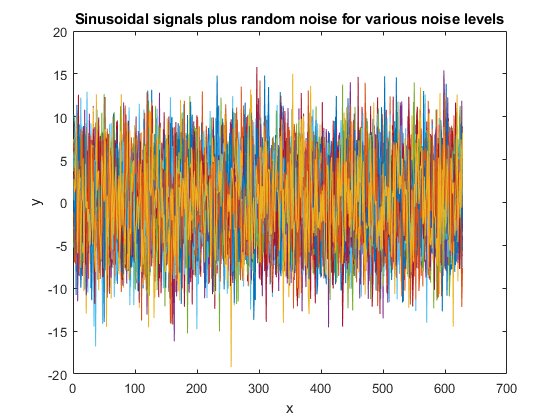

    reject(ii)=h;
    epsilonsave(ii)=epsilon;
end
xlabel('x');ylabel('y')
title('Sinusoidal signals plus random noise for various noise levels')

Plot the result of the experiment.

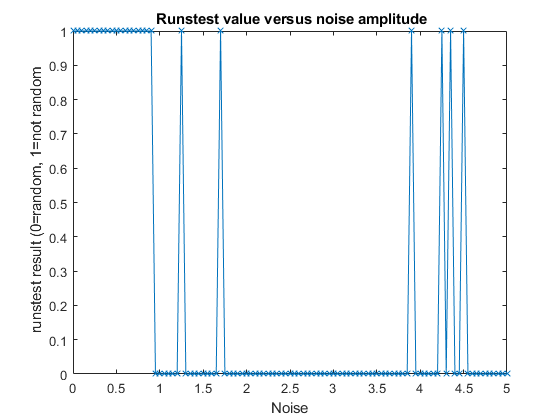

figure
plot(epsilonsave',reject','-x')
xlabel(' Noise ');
ylabel(' runstest result (0=random, 1=not random')
title(' Runstest value versus noise amplitude')